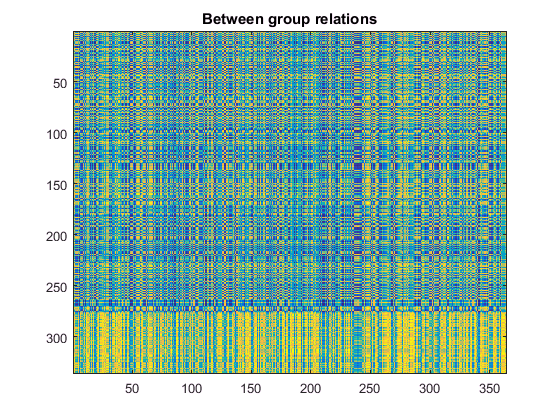

%% Generating the co-embedding
% replace the main.m in the LEDF_release with this script to obtain the
% result
close all
clear all
clc

rng(213);

%% load the associate data file
load('./Data/dot.mat');


%% The between group relation matrix
W    = CalRelationXY(X,Y,'gaussian','mean'); 
figure 
imagesc(W);
title('Between group relations');

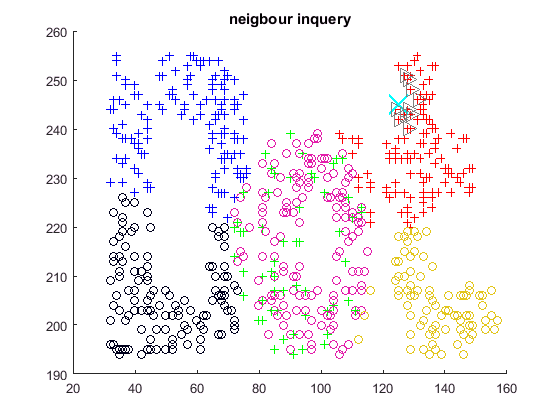



%% query for nearest neighbour and also visualize
figure;
Plotcluster(X',lx, Y',ly);
q = [125 245];
[n, d] = knnsearch(X, q, 'k', 10);
line(q(:,1),q(:,2),'marker','x','color','c',...
   'markersize',20,'linewidth',2,'linestyle','none')
line(X(n,1),X(n,2),'color',[.5 .5 .5],'marker','>',...
   'linestyle','none','markersize',10)
title('neigbour inquery');

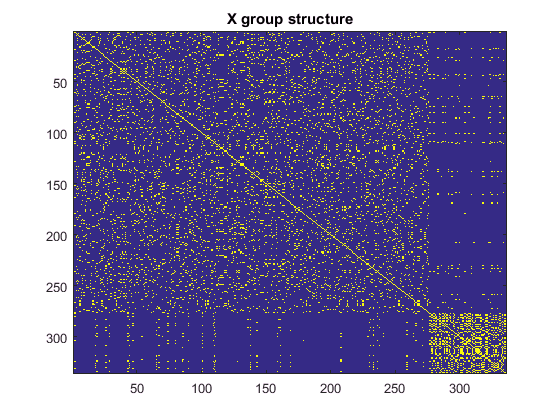


%% Build the linkages using neigbourhood methods
knn = 20;
[IDX, ~] = knnsearch(X, X, 'k', knn);
[M, ~] = size(X);
C = zeros(M);
for ii = 1 : M
    for jj = 1 : knn
        C(ii, IDX(ii,jj)) = 1;
    end
end
C=C|C.';
figure
imagesc(C);
title('X group structure');

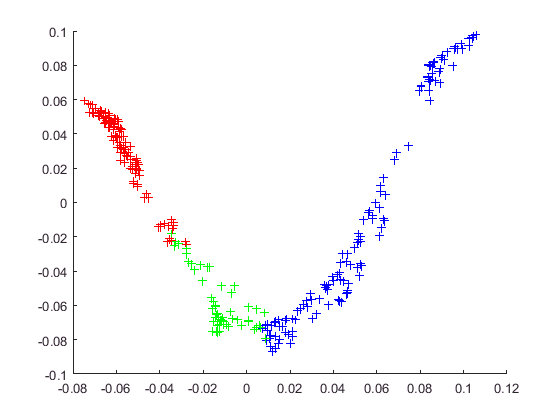



%% Symmetric Normalized Lapacian for X group data
%C=(C+C.')/2;
d = sum(C,2);
rd= 1./sqrt(d);
%[Xc, Cd] = eigs(@(x) x -rd.*(C*(x.*rd)) ,size(C,1),3, 'sm');

opts.issym = 1;
Lc =  eye(M) - bsxfun(@times,bsxfun(@times,C,rd), rd');
[Xc, Cd] = eigs( Lc ,4, 'sa', opts);
figure
Plotcluster(Xc(:,2:3)', lx);

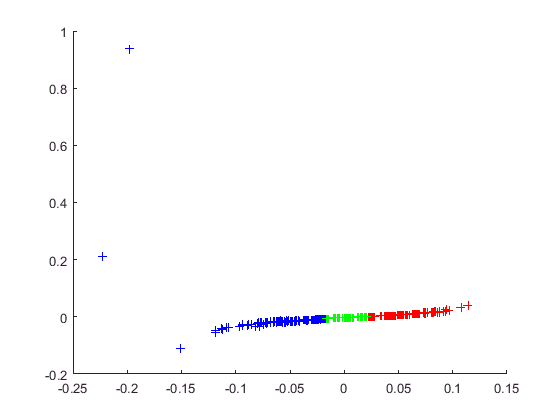

title('Laplacian embedding using C');

%% Heterogeneous embedding of documents
dr = sum(W, 2);
rdr = 1./sqrt(dr);
dc = sum(W,1);
rdc = 1./sqrt(dc);
W_ = bsxfun(@times, bsxfun(@times,W, rdr), rdc);

Dr = diag(sum(W_, 2));
dc_ = sum(W_, 1);

Lw = Dr - W_/diag(dc_)*W_';
[Xw, Wd] = eigs( Lw, 4,  'sm', opts);
figure
Plotcluster(Xw(:,2:3)', lx);

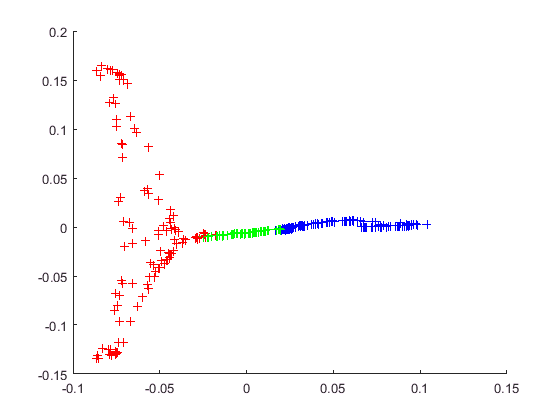

title('Laplacian embedding using W');

%% Joint diagonalization
[ V ,  qDs ]= joint_diag_r([Lw, Lc]);
figure
CostLc = diag(qDs(:,1:M));
CostLw = diag(qDs(:, M+1: 2*M));
Cost = CostLc + CostLw;
[B, I] = sort(Cost, 'ascend');
Plotcluster(V(:,I(2:3))', lx);

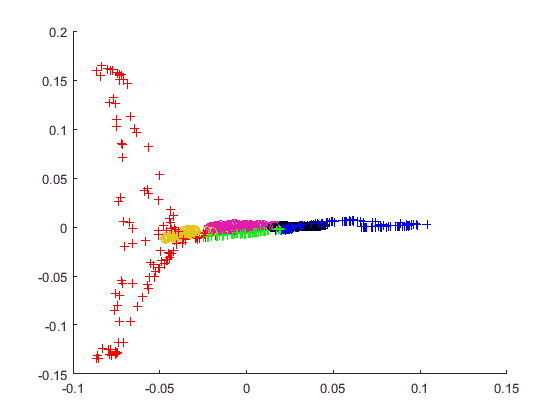


%% Plot the whole thing
Y = diag(dc_)\W_'*V (:,I(2:3));
figure
Plotcluster(V(:,I(2:3))', lx, Y', ly);